# Biomedical Signal & Image Processing

**Session 1**

@Autors 

Roham Kaveie - Ehsan Merikhi

## ECG Section

part 1) First, we load the ECG signal and display it for both channels in a certain period of time.P, Q, R, S, T waves are marked on the signal.

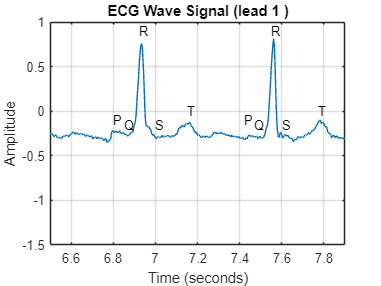

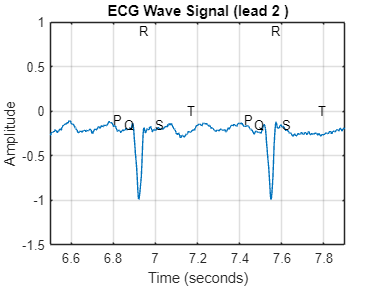

load('ECG_sig.mat')
L = length(Sig);
time = TIME(1:L);


for i = 1:2
    figure;
    plot(time,Sig(:,i));
    title(['ECG Wave Signal (lead ' num2str(i) ' )']); % Title of the plot
    xlabel('Time (seconds)');   % X-axis label
    ylabel('Amplitude'); 
    grid on;
    text(6.8,-0.1,'P');
    text(6.85,-0.15,'Q');
    text(6.92,0.9,'R');
    text(7,-0.15,'S');
    text(7.15,0,'T');
    text(7.42,-0.1,'P');
    text(7.47,-0.15,'Q');
    text(7.55,0.9,'R');
    text(7.6,-0.15,'S');
    text(7.77,0,'T');
    xlim([6.5 7.9])
    ylim([-1.5 1])
end

The shape of the beats over time is not the same for a channel and each heartbeat creates a different waveform than the previous one. Therefore, the ECG signal is called a quasi-periodic signal. Also The shape of the same beat on two channels is different from each other because these two leads are recorded from different places of the body.

part 2) For each R peak in the ECG signal, if an abnormality occurs in that beat, we write the type of abnormality below it.

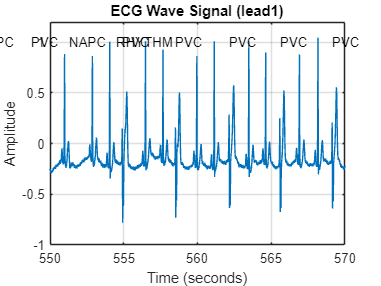


annotationNames = { ...
    'NOTQRS', 'NORMAL', 'LBBB', 'RBBB', 'ABERR', ...
    'PVC', 'FUSION', 'NPC', 'APC', 'SVPB', ...
    'VESC', 'NESC', 'PACE', 'UNKNOWN', 'NOISE', ...
    'ARFCT', 'STCH', 'TCH', 'SYSTOLE', 'DIASTOLE', ...
    'NOTE', 'MEASURE', 'PWAVE', 'BBB', ...
    'PACESP', 'TWAVE', 'RHYTHM', 'UWAVE', ...
    'LEARN', 'FLWAV', 'VFON', 'VFOFF', ...
    'AESC', 'SVESC', 'LINK', ...
    'NAPC', 'PFUS', ...
    'WFON', ...
    'WFOFF', ...
    'RONT'};

annotationCodes = [ ...
    0, 1, 2, 3, 4, ...
    5, 6, 7, 8, 9, ...
    10, 11, 12, 13, 14, ...
    16, 18, 19, 20, 21, ...
    22, 23, 24, 25, ...
    26, 27, 28, 29, ...
    30, 31, 32, 33, ...
    34, 35, 36, ...
    37, 38, ...
    39, 40, ... % PQ is defined as WFON (39)
    41, ...     % WFOFF
    ...         % JPT (40) is defined as WFOFF (40)
    ...         % RONT (41) is included
];
% Create a Map
ecgAnnotationsMap = containers.Map(num2cell(annotationCodes),annotationNames);

% Load Data
load('ECG_sig.mat');


% Plotting the signal
L = length(Sig);
time = TIME(1:L);
figure;                % Create a new figure
plot(time, Sig(:,1));      % Plot the signal
title('ECG Wave Signal (lead1)'); % Title of the plot
xlabel('Time (seconds)');   % X-axis label
ylabel('Amplitude');         % Y-axis label
grid on;                   % Turn on the grid
xlim([550 570]); 
ylim([-1 1.2]);
for i = [1:length(ANNOTD)]
    if ANNOTD(i)~=1
        code = ecgAnnotationsMap(ANNOTD(i));
        text(ATRTIMED(i),1,code);
    end
end

part 3) We separate and display a sample of the normal beat and any abnormality

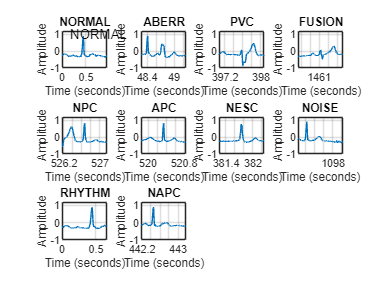

load("ECG_sig.mat")

annotationNames = { ...
    'NOTQRS', 'NORMAL', 'LBBB', 'RBBB', 'ABERR', ...
    'PVC', 'FUSION', 'NPC', 'APC', 'SVPB', ...
    'VESC', 'NESC', 'PACE', 'UNKNOWN', 'NOISE', ...
    'ARFCT', 'STCH', 'TCH', 'SYSTOLE', 'DIASTOLE', ...
    'NOTE', 'MEASURE', 'PWAVE', 'BBB', ...
    'PACESP', 'TWAVE', 'RHYTHM', 'UWAVE', ...
    'LEARN', 'FLWAV', 'VFON', 'VFOFF', ...
    'AESC', 'SVESC', 'LINK', ...
    'NAPC', 'PFUS', ...
    'WFON', ...
    'WFOFF', ...
    'RONT'};

annotationCodes = [ ...
    0, 1, 2, 3, 4, ...
    5, 6, 7, 8, 9, ...
    10, 11, 12, 13, 14, ...
    16, 18, 19, 20, 21, ...
    22, 23, 24, 25, ...
    26, 27, 28, 29, ...
    30, 31, 32, 33, ...
    34, 35, 36, ...
    37, 38, ...
    39, 40, ... % PQ is defined as WFON (39)
    41, ...     % WFOFF
    ...         % JPT (40) is defined as WFOFF (40)
    ...         % RONT (41) is included
];

% Create a Map
ecgAnnotationsMap = containers.Map(num2cell(annotationCodes),annotationNames);

% plot a sample of each abnormality
figure;
L = length(Sig);
time = TIME(1:L);
cnt = 0;
for i = annotationCodes
    indice = find(ANNOTD==i,1);
    if(~isempty(indice))
        be = max(ATRTIMED(indice)-0.5,0);
        en = min(ATRTIMED(indice)+0.5,time(L));
        cnt = cnt + 1;
        subplot(3,4,cnt);
        plot(time(round(be*sfreq+1):round(en*sfreq)),Sig(round(be*sfreq+1):round(en*sfreq),1))
        code = ecgAnnotationsMap(i);
        text(ATRTIMED(i),1,code);
        title(code); % Title of the plot
        xlim([be en]);
        ylim([-1 1.2]);
        xlabel('Time (seconds)');   % X-axis label
        ylabel('Amplitude');         % Y-axis label
        grid on;                   % Turn on the grid
    end
end

Below is a brief explanation about the abnormalities you see in the high beats.

## Aberrancy (ABERR)

Aberrancy refers to a condition where the conduction of electrical impulses through the heart is altered. This can lead to a widened QRS complex on the ECG. Aberrant conduction often occurs during episodes of tachycardia, where the impulse travels through the ventricles abnormally due to pre-existing bundle branch block or other conduction system issues.

## Premature Ventricular Contractions (PVC)

PVCs are early heartbeats originating from the ventricles. They are characterized by:

- A premature QRS complex that is typically wide and bizarre in shape.

- A compensatory pause following the PVC.PVCs can be benign or indicate underlying heart disease, especially if frequent or occurring in pairs or runs.

## Fusion Beats

Fusion beats occur when two electrical impulses reach the ventricles simultaneously, one from a normal pacemaker and another from an ectopic focus. This results in a QRS complex that has characteristics of both normal and abnormal beats, appearing as a hybrid. Fusion beats are often seen in patients with PVCs and can indicate the presence of both normal and abnormal conduction pathways.

## Non-Paced Contractions (NPC)

NPCs refer to heartbeats that occur without the influence of an artificial pacemaker. These can be either normal sinus beats or ectopic beats originating from various locations within the heart. The presence of NPCs can indicate issues with the heart's intrinsic conduction system.

## Atrial Premature Contractions (APC)

APCs are early contractions originating in the atria. They are characterized by:

- An early P wave that differs in shape from normal sinus P waves.

- A compensatory pause following the APC.APCs are common and often benign but can lead to more significant arrhythmias if they occur frequently.

## Non-Ectopic Sinus Contractions (NESC)

NESCs refer to sinus beats that occur without any ectopic activity influencing them. These beats originate from the sinoatrial node and maintain a regular rhythm, indicating normal atrial function. NESCs are typically seen in healthy individuals and reflect a stable cardiac rhythm.

## Non-Atrial Premature Contractions (NAPC)

NAPCs are contractions that arise from locations other than the atria, often from the ventricles or junctional tissues. They may be similar to PVCs but originate from different areas within the heart's conduction system. NAPCs can indicate underlying cardiac issues, particularly if they occur frequently or in conjunction with other arrhythmias.

4) We plot the frequency spectrum and the time-frequency spectrum for several consecutive normal strokes.

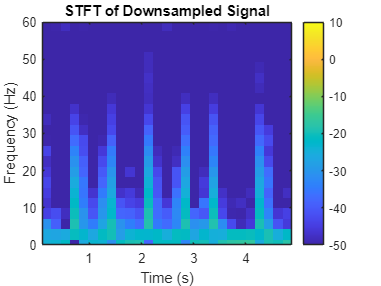

% Plot the STFT of the downsampled signal in a new figure
load("ECG_sig.mat")
figure;
window_length = 128;
noverlap = 64;
nfft = 128;
window = hamming(window_length);
spectrogram(Sig(round(sfreq*ATRTIMED(3)):round(sfreq*ATRTIMED(10)),1), window, noverlap, nfft, sfreq, 'yaxis');
title('STFT of normal beat');
ylim([0 60]);
colorbar;
caxis([-50 10]);  % Adjust this range for better contrast if needed

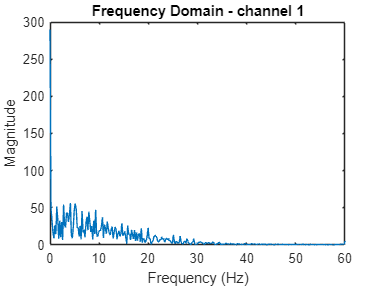



% Frequency domain using FFT (DFT)
N = length(Sig(round(sfreq*ATRTIMED(3)):round(sfreq*ATRTIMED(10)),1));  % Length of the signal
f = (0:N-1)*(sfreq/N);  % Frequency vector

% FFT of the left eye signal
fft_resp = abs(fft(Sig(round(sfreq*ATRTIMED(3)):round(sfreq*ATRTIMED(10)),1)));

plot(f, fft_resp);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Domain - normal beats');
xlim([0 60]);  % Limiting to 60 Hz for better visualization

We plot the frequency spectrum and the time-frequency spectrum for several consecutive abnormal strokes.

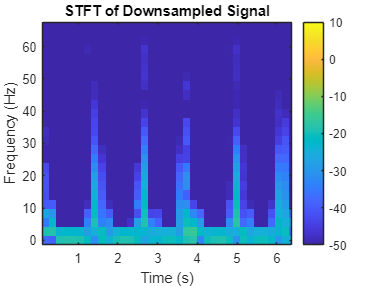

load("ECG_sig.mat")
figure;
window_length = 128;
noverlap = 64;
nfft = 128;
window = hamming(window_length);
spectrogram(Sig(round(sfreq*ATRTIMED(748)):round(sfreq*ATRTIMED(754)),1), window, noverlap, nfft, sfreq, 'yaxis');
title('STFT of abnormal beats');
ylim([0 60]);
colorbar;
caxis([-50 10]);  % Adjust this range for better contrast if needed

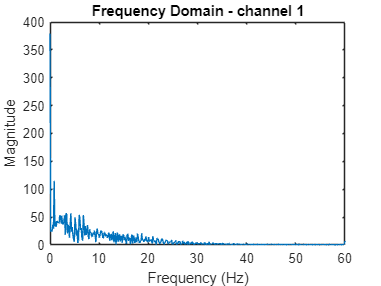


N = length(Sig(round(sfreq*ATRTIMED(748)):round(sfreq*ATRTIMED(754)),1));  % Length of the signal
f = (0:N-1)*(sfreq/N);  % Frequency vector


% FFT of the left eye signal
fft_resp = abs(fft(Sig(round(sfreq*ATRTIMED(748)):round(sfreq*ATRTIMED(754)),1)));

plot(f, fft_resp);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Domain - abnormal beats');
xlim([0 60]);  % Limiting to 60 Hz for better visualization

In the following, you can see the differences in the frequency spectrum of normal and PVC beats.